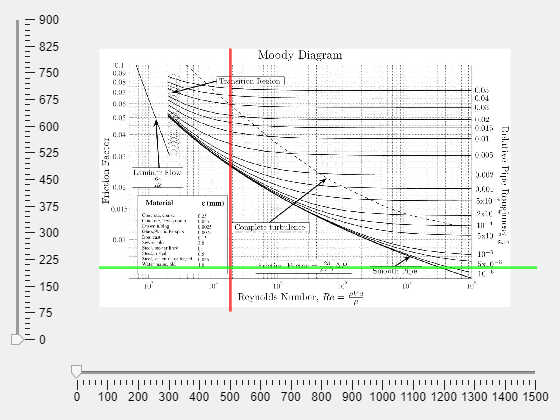

% Inicio de la aplicación
fig = uifigure;
fig.Name = "My app";

% Visualización
% fig.Visible = "off";

% Cuadrícula
gl = uigridlayout(fig, [3 3]);
gl.RowHeight = {"1x", "1x", 50};
gl.ColumnWidth = {50, "1x", "1x"};

% Componentes
sh = uislider(gl);
sv = uislider(gl, "Orientation", "vertical");
ax = uiaxes(gl);

img = imread("Moody-chart-min.jpg");
imshow(img, "Parent", ax);

x_init = (ax.YLim(2) - ax.YLim(1)) / 2;
y_init = (ax.XLim(2) - ax.XLim(1)) / 2;
hLineV = xline(ax, x_init, 'r', 'LineWidth', 2);
hLineH = yline(ax, y_init, 'g', 'LineWidth', 2);

% Ubicación de los componentes
sh.Layout.Row = 3;
sh.Layout.Column = [2 3];
sh.Limits = ax.XLim;

sv.Layout.Row = [1 2];
sv.Layout.Column = 1;
sv.Limits = ax.YLim;

ax.Layout.Row = [1 2];
ax.Layout.Column = [2 3];

% Asignar las llamadas
sh.ValueChangedFcn = @(sld, event) actualizar_linea_vertical(sld, hLineV);
sv.ValueChangedFcn = @(sld, event) actualizar_linea_horizontal(sld, hLineH);

function actualizar_linea_horizontal(slider, hLineH)
    newY = slider.Value;
    valor_minimo = slider.Limits(1);
    valor_maximo = slider.Limits(2);
    rango = valor_maximo - valor_minimo;
    porcentaje = (newY - valor_minimo) / rango;
    newY = valor_maximo - porcentaje * rango;
    hLineH.Value = newY;
end

function actualizar_linea_vertical(slider, hLineV)
    newX = slider.Value;
    hLineV.Value = newX;
end